# Continuous Population Models II: Logistic Growth

**Mathematical skills:** arithmetics, equations, functions, graphs

**Coding extras:** Tables, solving differential equations with conditions, plots, assigning values, symbolics 

**Task: **Read the intro. Then, modify the code to answer the questions in the Questions section. 

**Criteria**: This lesson is packed, so you might be wondering what do I really need to know after completing it? Here are some checkboxes to guide you:

- Can you tell whether a graph shows exponential growth or logistic growth?

- Can you change the carrying capacity so that the population grows to be larger at large times?

If you answered a confident 'yes' to these, you're all set! Good job. If the answer was less confident, try finding the sticky parts and let your instructor know. Pace check is always nice.

## Intro

Last time we added a new model to our toolbox: exponential growth. Although this simple toy model gave us a good example to start working with continuous models, it has its limits. For instance, as you saw in the table or the graph, it predicted that after a day or eventually, we would be swimming in an infinite pool of bacteria! Since we know that is not the case, we have to revisit our assumptions.   

    Remember how we talked about ideal growth circumstances? Well, that might be true for a hours in a lab where bacteria have unlimited access to nutrients but after a while, the food is going to run out (unless we restock it!). There are many different ways of including this assumption of nutrient consumption in a population model, and a simple one is called the ***logistic model***. In this model, we assume that there is a limit to how much of the population the environment can accomodate, called **carrying capacity. **The model restricts the population number to grow past this capacity. We will use `B` to refer to this variable. Additionally, we have r`,` which denotes the intrinsic growth rate.  

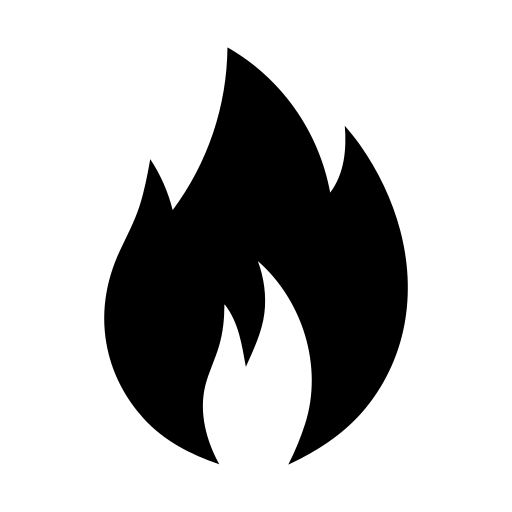**Hot** **Question:** Before running the code, can you take a guess at what the graph might look like?

Again, the main goal with this model is to predict the population density N(t) at any time t given an initial density N0. In the previous example (exponential growth) we assumed that the reproduction rate, K, was a positive number and constant. To make the model realistic, we assume that K could change as time goes on. More specifically, in the logistic growth model, it takes the following form:

$K\left(t\right)=r\left(1-\frac{N\left(t\right)}{B}\right)\ldotp$                                      Equation 1

To calculate N(t), we solve

$\frac{\textrm{dN}\left(t\right)}{\textrm{dt}\;}=K\left(t\right)N\left(t\right)$,                            Equation 2

where this time, K(t) changes with time.

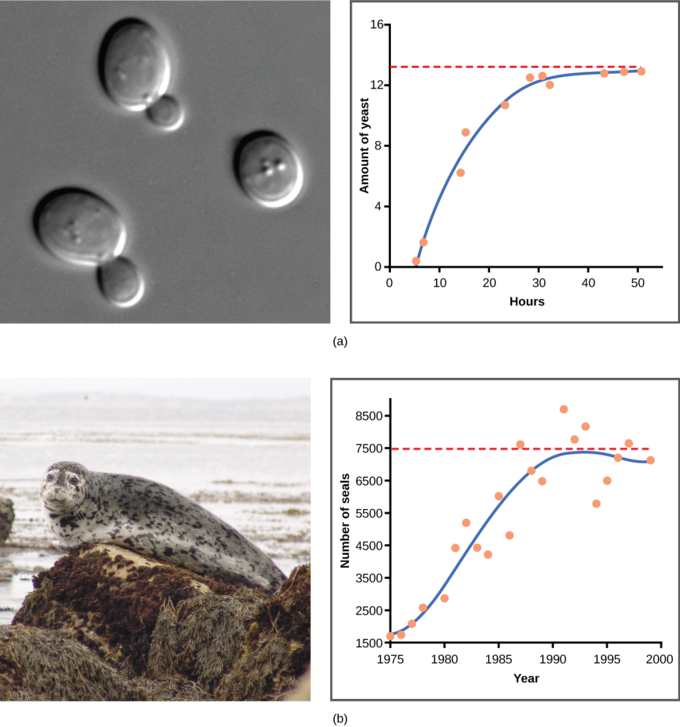

Figure taken from bio.libretexts.org (a) Yeast grown in ideal conditions in a test tube shows a classical S-shaped logistic growth curve, whereas (b) a natural population of seals shows real-world fluctuation. The yeast is visualized using differential interference contrast light micrography. (credit a: scale-bar data from Matt Russell)

## Code

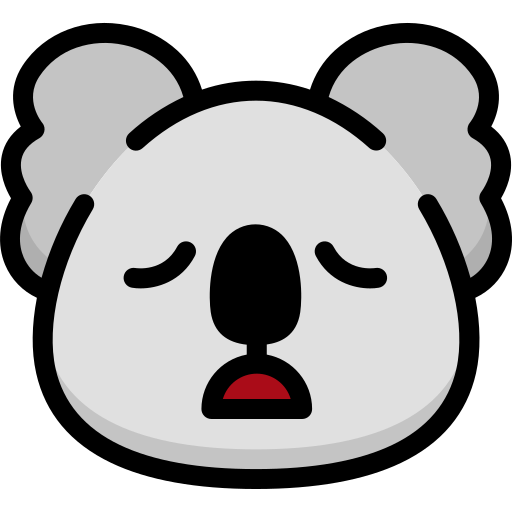 After another hefty intro, we are at the section that you will modify later to use. Congratulations on making it this far. I'm sure the Owl with the tips is proud. 

Like usual, we set the initial population density `N0` and,` T_final,` the final time that we are interested in, say 6 hours later:

N0 = 1000000; % unit:cells/ml 
T_final = 6; % unit: hours

Here, instead of the reproduction rate K, we set the carrying capacity B and the intrinsic growth rate r:

B = 8000000; % unit:cells/ml 
r =1;

**Tip:** use the slider to play with the value of `r` and watch how it changes graph.

Again, we use a MATLAB symbolic solver to solve Equation 2. If you would like to see the details, head to the functions section and look at the code used for the function `ContPopModelLog(K,N0)`.

LogModel = PopModelLogistic(B,r,N0)

$$LogModel(t) = \frac{8000000\,{\mathrm{e}}^{t}}{{\mathrm{e}}^{t}+7}$$

Let's also use the exponential growth model to compare the results that we get from these two models:

ExpModel = ContPopModelExp(r,N0)

$$ExpModel(t) = 1000000\,{\mathrm{e}}^{t}$$

The table below compares the values of the population density at different times [0; 1 minute, 1 hour, 6 hours, 1 day] for the two models:

Times = [0; 1/60; 1; 6; 24];
T = table(Times, double(ExpModel(Times)),double(LogModel(Times)))

T = 5×3 table
     Times         Var2          Var3   
    ________    __________    __________

           0         1e+06         1e+06
    0.016667    1.0168e+06    1.0147e+06
           1    2.7183e+06    2.2377e+06
           6    4.0343e+08    7.8636e+06
          24    2.6489e+16         8e+06


## Graphs

Let's compare the results visually:

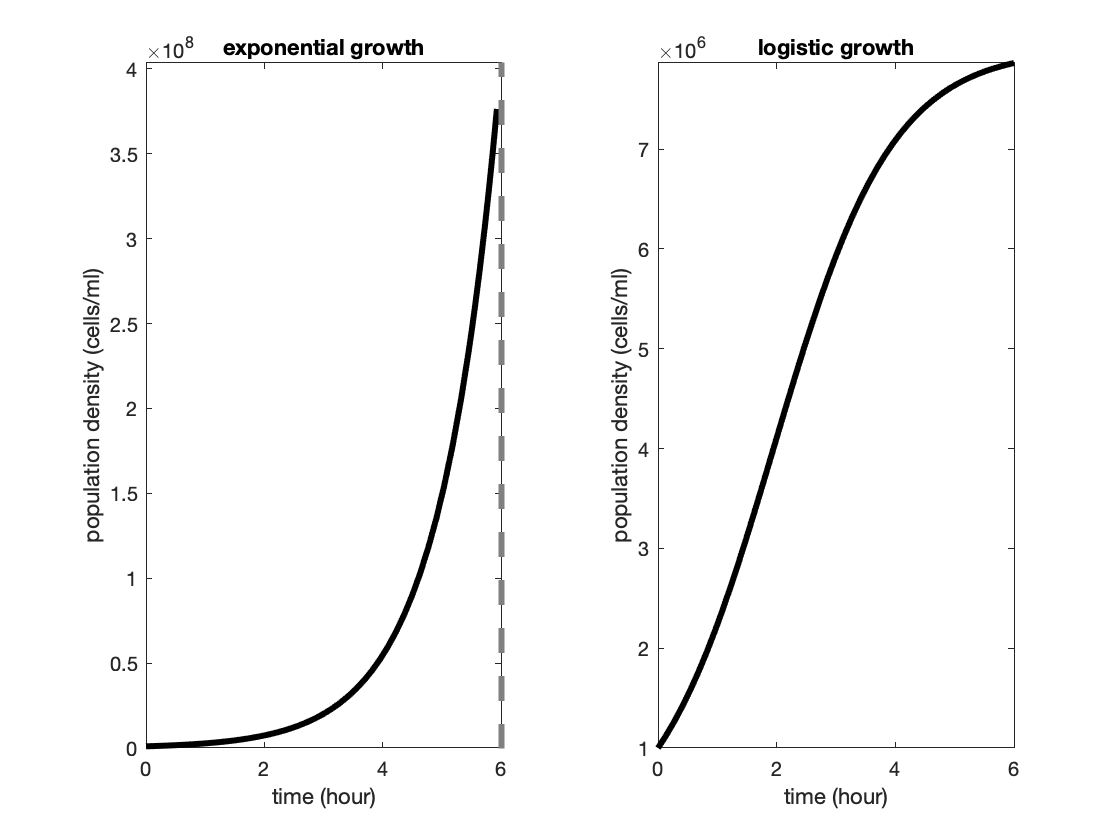

plotPopulations(ExpModel,LogModel,T_final,1)
hold off

We could also plot the two curves on the same graph to make it easier to compare them:

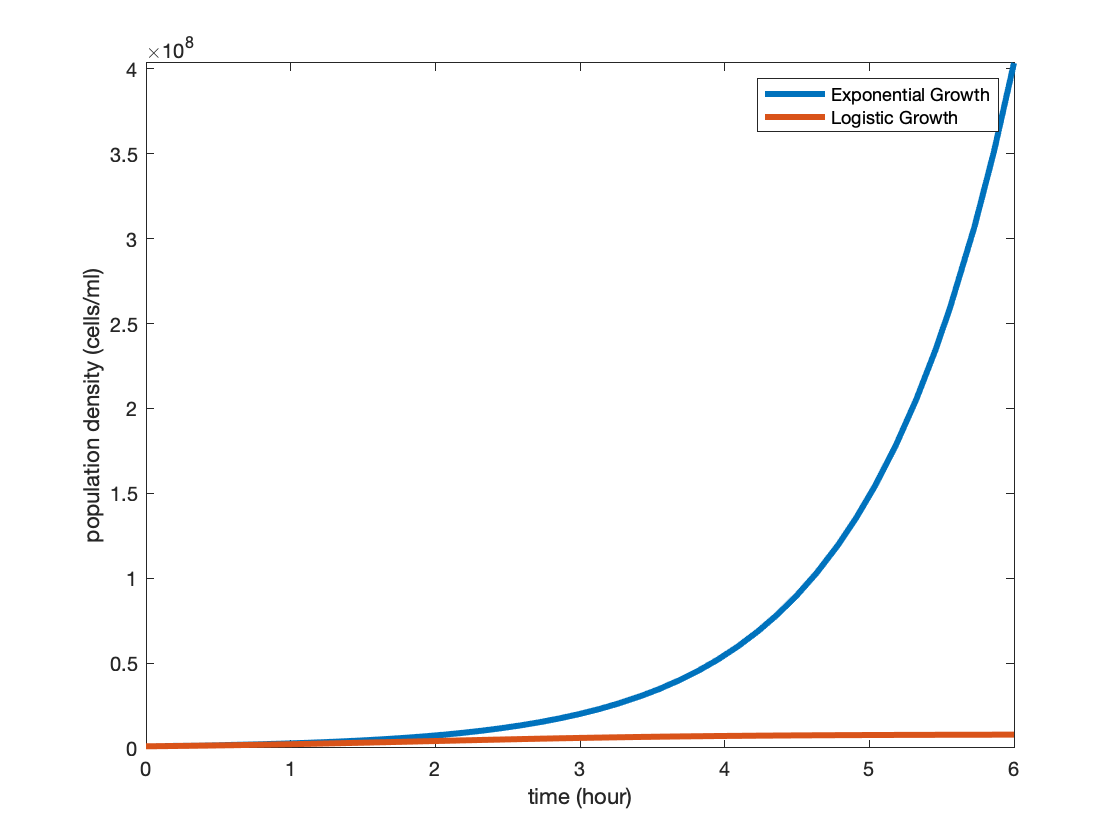

figure
fplot(ExpModel,[0 T_final], 'LineWidth', 3, 'DisplayName', 'Exponential Growth')
hold on;
fplot(LogModel,[0 T_final], 'LineWidth', 3, 'DisplayName', 'Logistic Growth')

% insert label for the x-axis
xlabel('time (hour)')
% insert label for the y-axis
ylabel('population density (cells/ml)')
% display legend
legend

Oops! You may have noticed that since one of the curves ranges in a much wider interval of values, it is imporssible to see how the other one changes. There's a trick to solving this issue. Instead of using a regular ruler for our y-axis, we use a logarithmic one. We use the following piece of code to do so:

 fun(?) fact: I Googled how to change the YScale to make sure I had the right code.

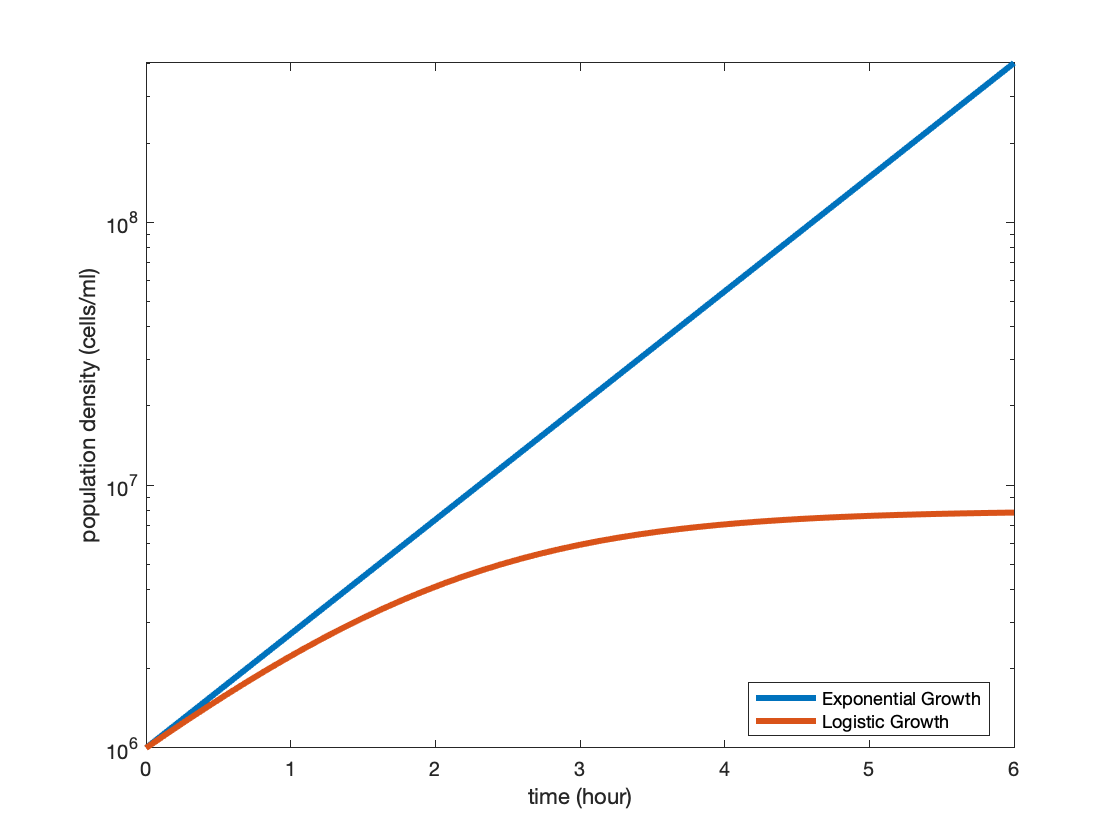

figure
fplot(ExpModel,[0 T_final], 'LineWidth', 3, 'DisplayName', 'Exponential Growth')
hold on;
fplot(LogModel,[0 T_final], 'LineWidth', 3, 'DisplayName', 'Logistic Growth')
set(gca, 'YScale', 'log') 
% insert label for the x-axis
xlabel('time (hour)')
% insert label for the y-axis
ylabel('population density (cells/ml)')
% display legend
legend('Location','best')

## Questions

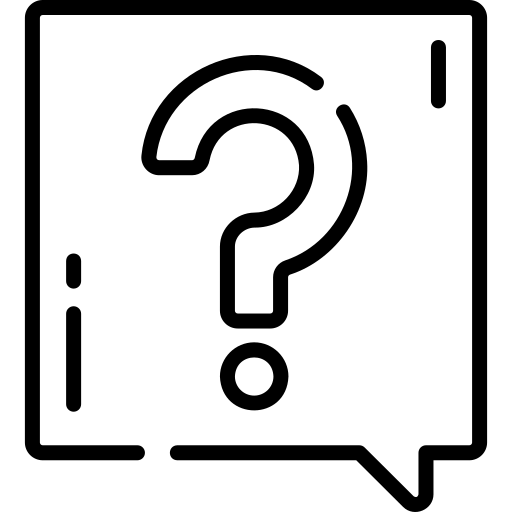 **Question 1:** What is the population density according to the logistic model after 6 hours when r = 1, the carrying capacity is 2 million cells/ml and starting population 1 million cells/ml? 

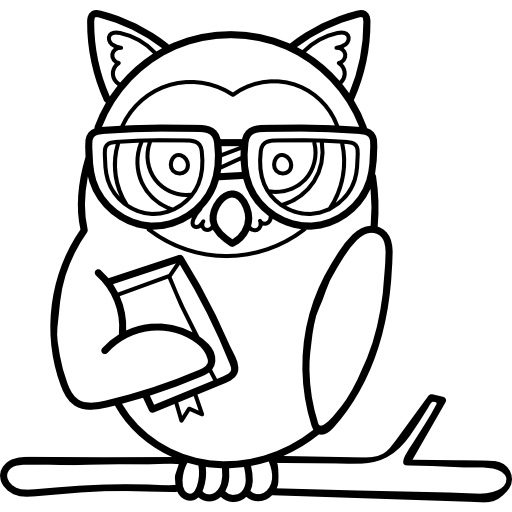  **Owl Tip: **You can either use the table above or the following snippet of code in the command line for a quick answer. Make sure you modify the variables the code and run it first!

 **Question 2:** What is the population density according to the exponential growth model after 6 hours when r = 1 and N0 = 1,000,000 cells/ml? 

 **Question 3:** By how much does the population density change according to the logistic model after 6 hour when **r = 1**, the carrying capacity is **8 million cells/ml** and starting population **1 million **cells/ml? 

  **Owl Tip: **You can either use the table above or the following snippet of code in the command line for a quick answer.

 **Question 4:** What happens in the logistic model when the starting population is more than the carrying capacity? What happens when they are the same? Does it make sense and how cool is that?

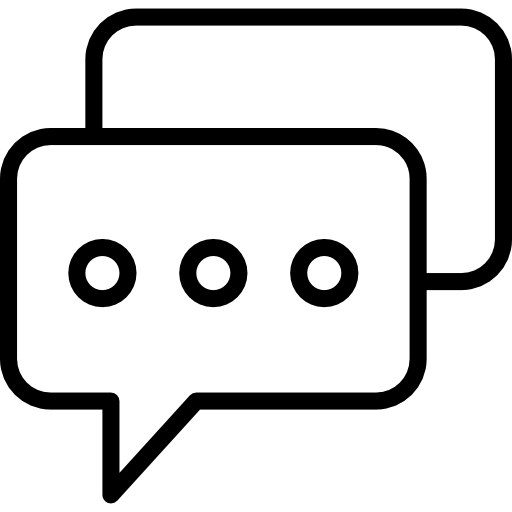 **Question 5:** Can you think of some of the limitations of the logistic growth model?

 **Question 6:** What concepts are still confusing? What more examples can help? What skills do you need more help with?

## Functions

function ExpModel = ContPopModelExp(K,N0)
syms  N(t)
eqn = diff(N, t) == K*N;
cond = N(0) == N0;
ExpModel(t) = dsolve(eqn,cond);

end

function LogModel = PopModelLogistic(B,r,N0)
syms  N(t)
K = r*(1-N(t)/B);
eqn = diff(N, t) == K*N;
cond = N(0) == N0;
LogModel(t) = dsolve(eqn,cond);

end



function plotPopulations(NSol1,NSol2,T_final,d)

if d > 0
    tilenumber = 2;
else 
    tilenumber = 1;
end

Tvec = [0 T_final];


tiledlayout(1,tilenumber)
% panel 1
nexttile
% here, we plot the population density as a function of time
fplot(NSol1,Tvec, 'LineWidth', 3, 'Color','k')
% insert label for the x-axis
xlabel('time (hour)')
% insert label for the y-axis
ylabel('population density (cells/ml)')
% insert title
title('exponential growth')

if d > 0
    % panel 2
nexttile
    % here, we plot the population density as a function of time
    fplot(NSol2,Tvec, 'LineWidth', 3, 'Color','k')
    % insert label for the x-axis
    xlabel('time (hour)')
    % insert label for the y-axis
    ylabel('population density (cells/ml)')
    % insert title
    title('logistic growth')
end

end

## References

For further reads, see:

[Bio.Libretexts.org](https://bio.libretexts.org/Bookshelves/Ecology/Environmental_Biology_(Fisher)/04%3A_Community__Population_Ecology/4.02%3A_Population_Growth_and_Regulation)

Mathematical Models in Biology by Leah Edelstein-Keshet

Attributions: icons are from flaticon.com